# **PWM - Loopback **

This example demonstrates the use of the PWM Generation v5 and PWM Capture v1 driver blocks. The model is set up for a loop back configuration. PWM pulses are emitted from two PWM Generation v5 channels. The signals are looped back on the terminal board to be detected by four PWM Capture v1 channels. This example shows how to generate and capture different types of PWM signals.

## Setup

### Prerequisites

You require the following to run this example:

- Speedgoat real-time target machine with one configurable I/O module from the IO3xx family

- A Speedgoat configuration file that supports **2x PWM channels including A, B and Trigger** **lines, as well as** **4x PWM capture channels, including Trigger lines**  

- Connector cable from the I/O module to the terminal board

- Terminal board with jumper wires

### Test Setup

In this example, PWM pulses are emitted from two PWM Generation v5 channels and captured by four PWM Capture v1 channels. You must therefore connect the corresponding pins on the terminal board as indicated in the following pin wiring table. The exact pins depend on your specific configuration file (bitstream). 

In the pin mapping of your configuration file, locate the functionalities specified in the table below and then locate the corresponding pins on the terminal board. Connect these pins with jumper wires.

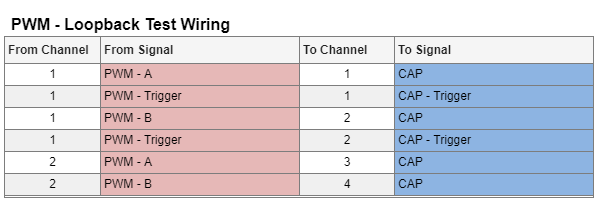

Ensure that you connect the trigger output of PWM channel 1 to both trigger inputs of CAP channels 1 and 2.

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO3xx_PWM_Loopback';
open_system(modelName);

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select the configuration file that supports the required functionalities.

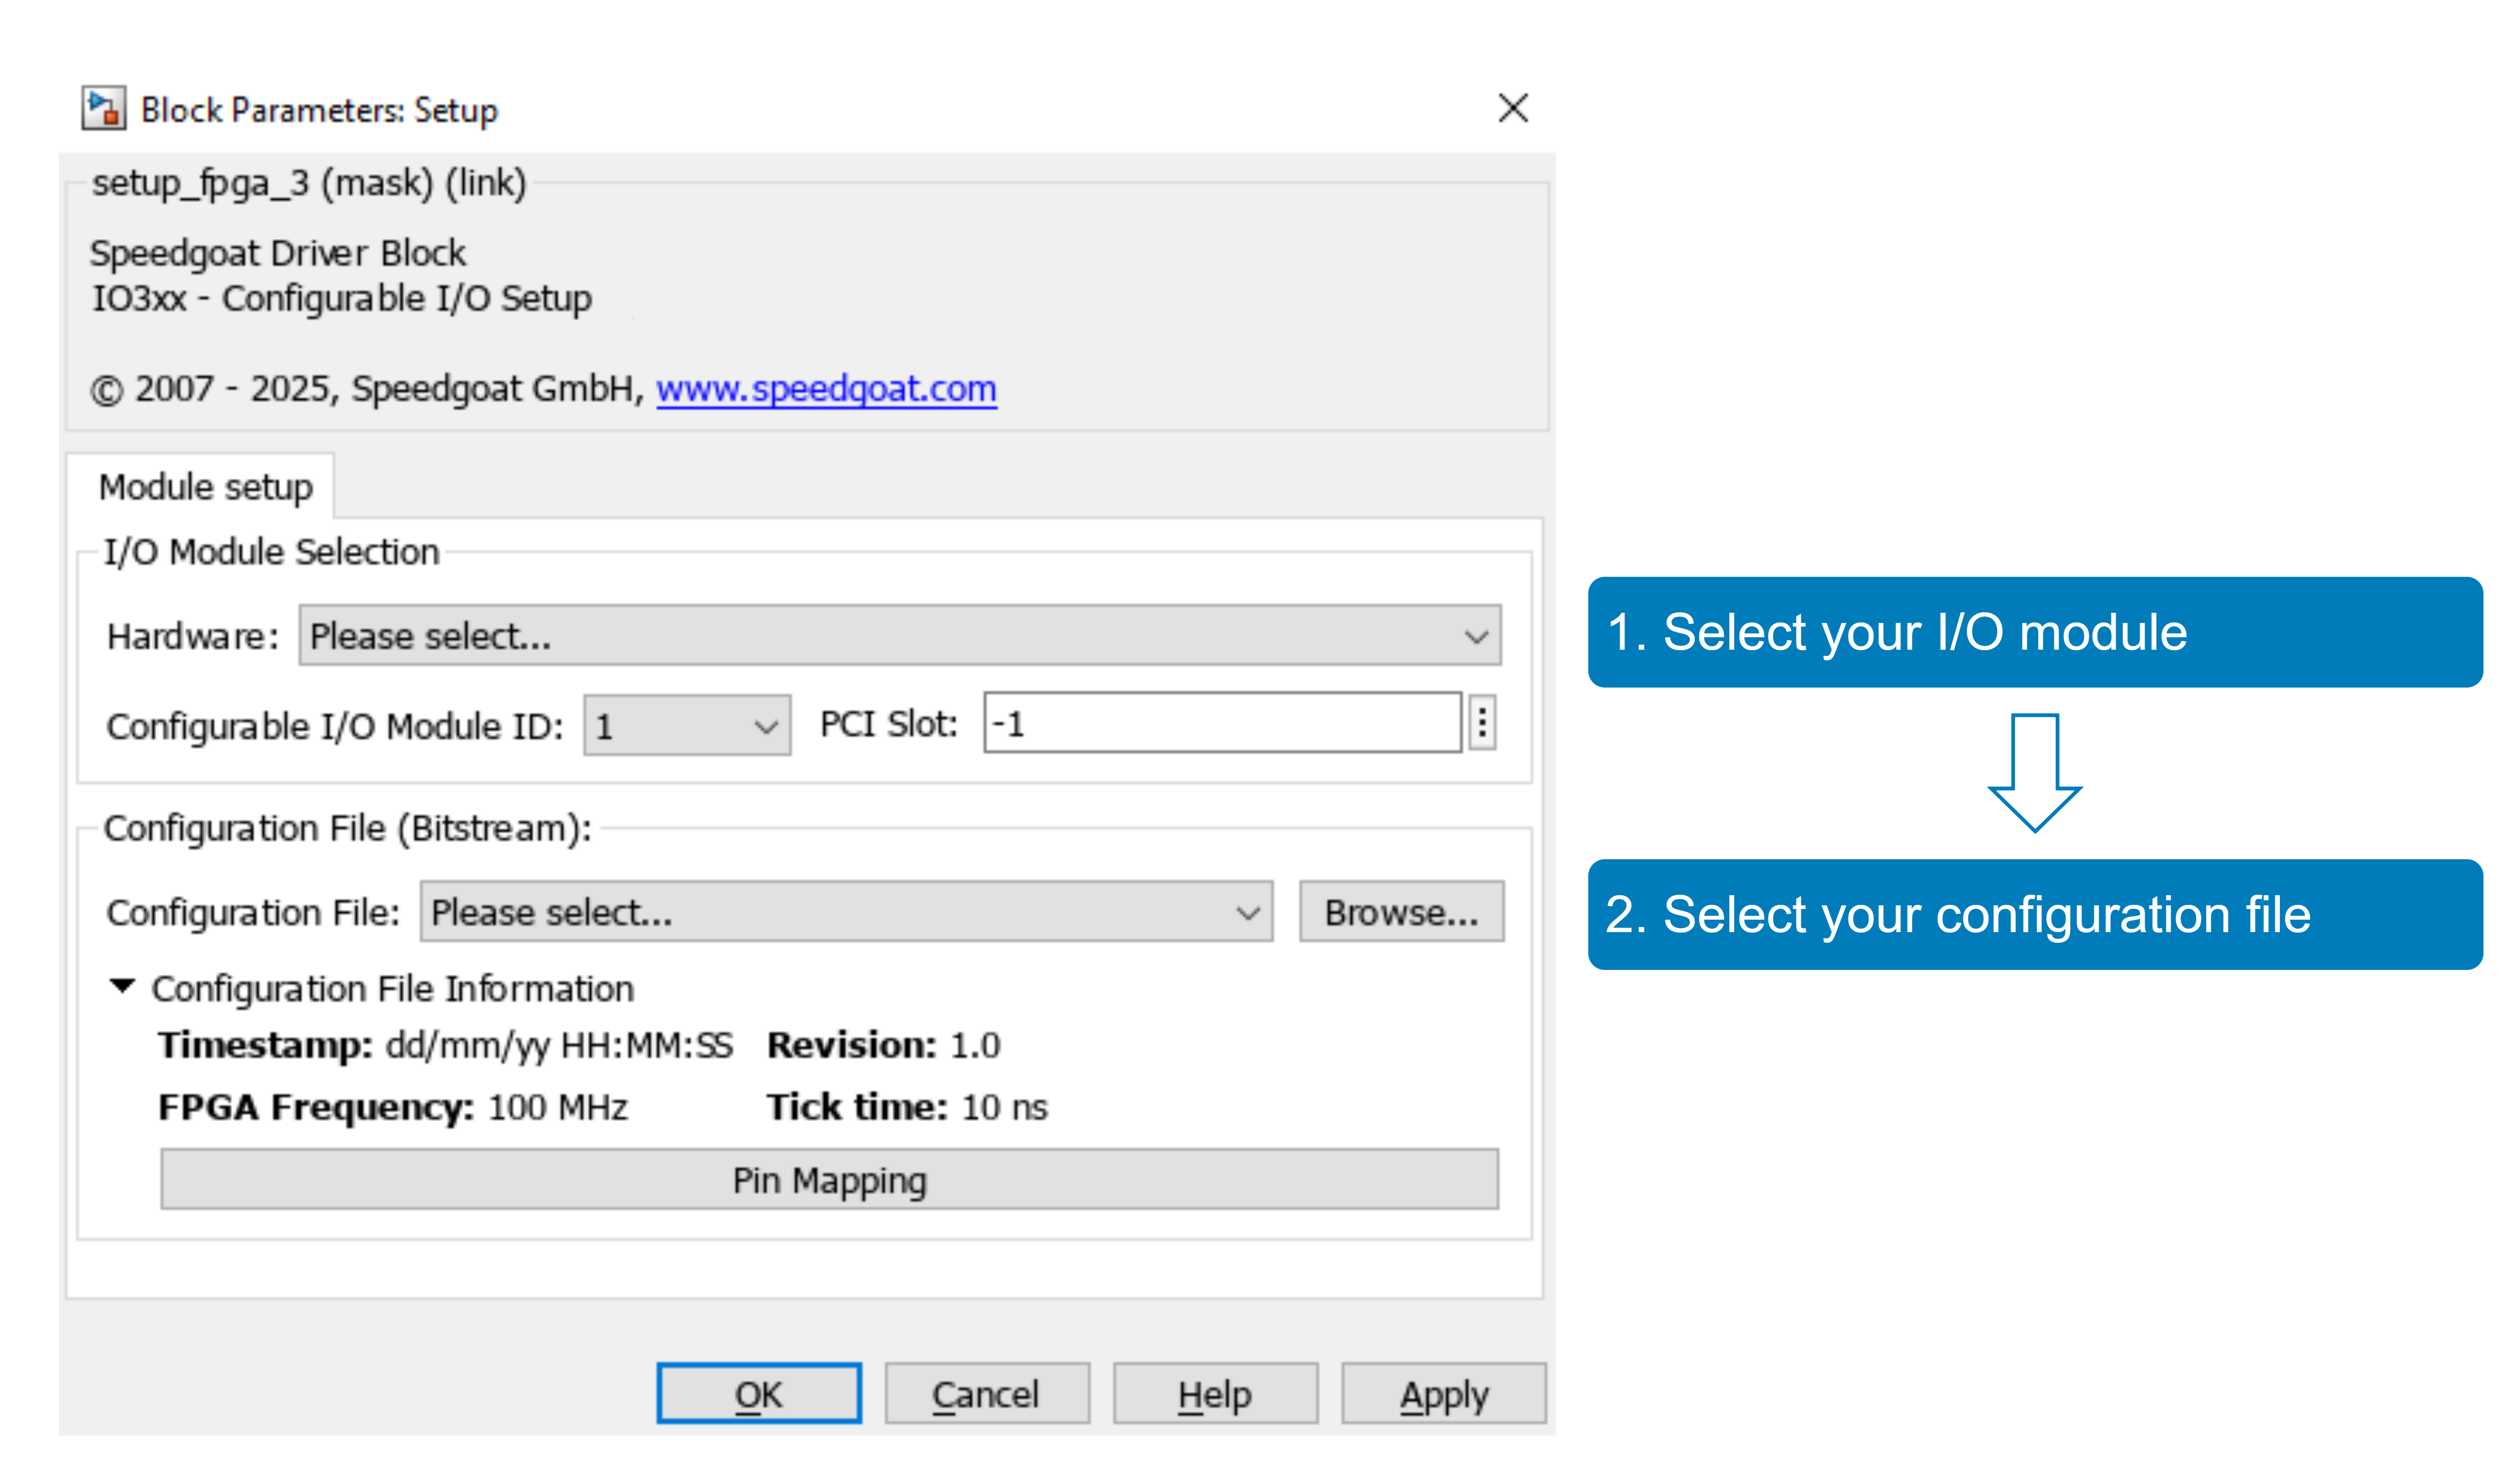

With the **Pin Mapping** button you can now check where the functionalities are located.

This model uses a sample time of 1 ms. The PWM frequency is 1 kHz.

% specify sample times
Ts = 1e-3;
Tpwm = 1e-3;

## Model Description 

### PWM Generation

The model contains two instances of the PWM Generation v5 block. The first instance is assigned to PWM channel 1 (**Channel Vector** parameter). The block is configured to generate a pair of complementary symmetric PWM signals (A and B). The settings in the **PWM Generation** tab of the driver block mask are:

- **PWM Pattern is:** Symmetric - PWM generation is centered around half the period

- **PWM B Output is:** The complement of PWM A output

The duty cycle of the signal is directly defined by the **PWM A/ #B DC** input port which is connected to a sine wave signal. The signal range is between 0 and 1. The trigger output of PWM channel 1 is configured to generate a pulse of 1 us at the beginning of each PWM period. This is defined in the **Triggering** tab of the block mask.

The second instance of the PWM Generation v5 block is assigned to PWM channel 2. The block is configured to generate two asymmetric PWM signals (A and B). The trigger output is not active. The signals share the same carrier. However, Ton and Toff are defined independently for both signals by the four input ports of the block.

- **PWM Pattern is:** Asymmetric - On and Off are freely configurable

- **PWM B Output is:** Independent of PWM A output

The **A-On** input is constantly 0 while the **A-Off** input is connected to the sine wave block. This leads to a "left-aligned" PWM signal with the rising edge occurring right at the start of each period. The **B-Off** input is connected to a constant and is equal to the period length. The B-On input is altered by the sine wave block. This leads to a "right-aligned" PWM signal with the falling edge occurring right at the period end. Note that the sine wave amplitude exceeds the PWM period length. We therefore obtain an overmodulated PWM signal at the tip and bottom of the sine wave.

The PWM period of both channels is 1 ms. This is defined in the **Initial Period Vector** parameter of the block mask. The **Initial Period Vector** defines a constant PWM period, unless the **Show Period Input Port** option is enabled in the **Input Ports Configuration** tab.

### PWM Capture

The model contains three instances of the PWM Capture v1 block. The first instance is configured to capture the complementary PWM signals A and B of PWM channel 1. The **Capture Mode** is set to **Use Dedicated Trigger Input**. This means that the PWM period is well defined by two consecutive rising edges of the trigger signal. A debounce input filter of 100 ns is defined which applies for all input signals (PWM input and trigger). The block has the following outputs configured in the **Input and Output Port Configuration** tab:

- High: This output signal is the number of FPGA clock ticks during which the input signal was high during one PWM period

- Period: This output signal is the length of a PWM period in FPGA clock ticks. In this case, it is the number of clock ticks between two consecutive trigger pulse rising edges

- DC16: This output signal is the captured duty cycle of the PWM signal with a resolution of 16 bits (the output signal is converted to double data type)

The second and third instances of the PWM Capture v1 block are used to capture the A and B signals of PWM channel 2. The **Capture Mode** is set to **High Transition Triggered** for signal A and **Low Transition Triggered **for signal B. This means that the block interprets the duration between two rising or falling edges of the PWM signal as one PWM period.

The **Capture Timeout Vector [s]** is used to reset the internal period counter if the duty cycle of the input signal is either 1 or 0. No signal edges can be detected to define the PWM period duration if the duty cycle value is 1 or 0. The **Capture Timeout Vector [s]** is set to 110 % of the expected PWM period to detect overmodulation.

The blocks have the following outputs configured in the **Input and Output Port Configuration** tab:

- High: This output signal is the number of FPGA clock ticks during which the input signal was high during one PWM period

- Low: This output signal is the number of FPGA clock ticks during which the input signal was low during one PWM period

- DC16: This output signal is the captured duty cycle of the PWM signal with a resolution of 16 bits (the output signal is converted to double data type).

- Valid Data Flag: This binary output indicates whether the data at the other output ports is valid 

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode  

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

Open the Simulink scopes in the model to verify that the loopback is wired correctly. 

In Scope 1 you can see:

**Top:** The detected period length of PWM channel 1 signals A and B in FPGA clock ticks. The period length is detected based on the trigger inputs and is the same for both signals. You can also see the high duration of the complementary signals.

**Middle:** The duty cycle of both signals computed based on the High and Period outputs.

**Bottom:** The duty cycle of both signals obtained directly from the DC16 output of the PWM Capture v1 block.

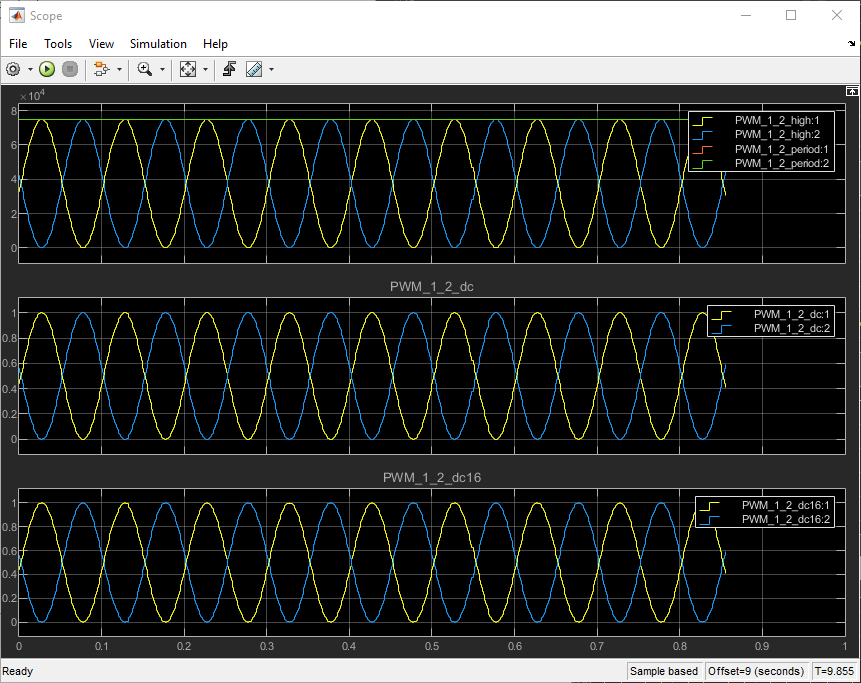

In Scope 2 you can see:

**Top:** The detected high duration of PWM channel 2 signal A. 

**Middle:** The detected duty cycle of PWM channel 2 signal A.

**Bottom:** The valid signal at the output of the second PWM Capture v1 block. The block indicates invalid data when the PWM signal is in overmodulation (duty cycle either 0 or 1) because the **Capture Mode** is set to **High Transition Triggered**. The overmodulation is detected based on the **Capture Timeout Vector **defined.

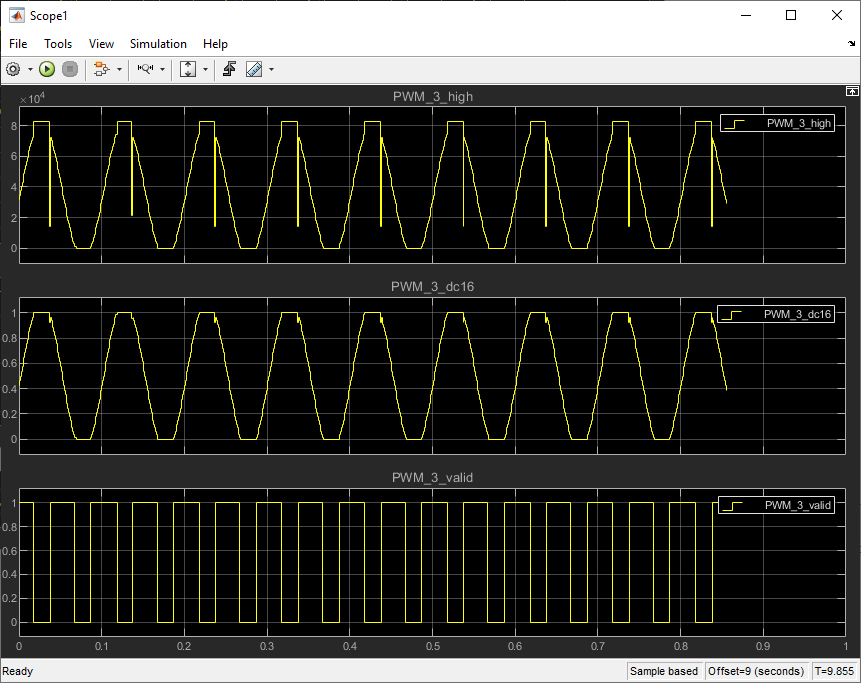

In Scope 3 you can see:

**Top:** The detected high duration of PWM channel 2 signal B. 

**Middle:** The detected duty cycle of PWM channel 2 signal B.

**Bottom:** The valid signal at the output of the third PWM Capture v1 block. The block indicates invalid data when the PWM signal is in overmodulation (duty cycle either 0 or 1) because the **Capture Mode** is set to **Low Transition Triggered**. The overmodulation is detected based on the **Capture Timeout Vector **defined.

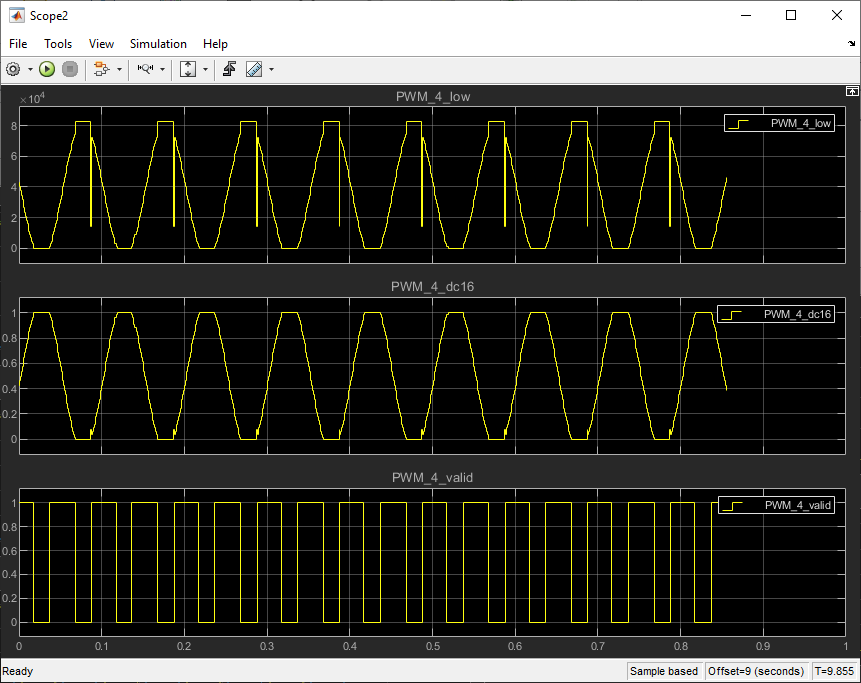

## Additional References

- [PWM documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_pwm)